# PDE

## `证明抛物线型方程FTCS方法的稳定条件`

`Let `$$\delta_{n}(x)=\sum_{k} \delta_{k}^{n} e^{i k x}$$

`substitute into equation`


$$$$
u_{j, n+1}=(1-2 \beta) u_{j,n}+\beta\left(u_{j-1, n}+u_{j+1, n}\right)
$$
$$


`where `$ $\beta=\frac{D \Delta t}{\Delta x^{2}}$$

`We then have`


$$$$
\delta_{k}^{n+1} e^{i k x_{j+1}}=(1-2 \beta) \delta_{k}^{n} e^{i k x_{j}}+\beta\left(\delta_{k}^{n} e^{i k x_{j-1}}+\delta_{k}^{n} e^{i k x_{j+1}}\right)
$$$$


`the stable condition requires that `$$\forall k, \quad|g| \le 1$$


$$\Rightarrow |g|=\left(1-4 \beta \sin ^{2} \frac{k \Delta x}{2}\right)^{2} \le 1$$



$$$$
\matrix{
\Rightarrow &|g|=\left(1-4 \beta \sin ^{2} \frac{k \Delta x}{2}\right)^{2} \le 1 \cr
\Rightarrow & \beta \sin ^{2} \frac{k \Delta x}{2}\left(1-2 \beta \sin ^{2} \frac{k x}{2}\right) \ge 0 \cr
\text { in extreme condition } \sin \frac{k \Delta x}{2}=1 \cr
\Rightarrow & 0 \leq \beta \leq \frac{1}{2}, \quad \text{i.e.}\cr
& \frac{D \Delta t}{\Delta x^{2}} \le \frac{1}{2}
}
$$$$


## 使用CN方法重新求解扩散问题


$$\frac{\partial u}{\partial t}-\frac{\partial^{2\;} u}{\partial x^2 }=0\;\left(0\le x\le 1,t>0\right)$$


初始条件 


$$u\left(x,0\right)=\sin \left(\pi \;x\right)$$


边界条件


$$u\left(0,t\right)=u\left(1,t\right)=0$$


精确解为


$$u\left(x,t\right)=\sin \;\left(\pi \;x\right)e^{-\pi^2 t}$$


tSpan=[0,1];tSlice=1000;
xSpan=[0,1];xSlice=1000;
dt=diff(tSpan)/tSlice;
dx=diff(xSpan)/xSlice;
x=linspace(xSpan(1),xSpan(2),xSlice);
t=linspace(tSpan(1),tSpan(2),tSlice);

% column vector is a slice at certain time.
u=zeros(xSlice,tSlice);
% Diffusion coefficient
D=1;

gamma=D*dt/(2*dx^2);


% generating the CN Matrix
A=diag(repmat([1+2*gamma],xSlice,1))+diag(repmat([-gamma],xSlice-1,1),-1)+diag(repmat([-gamma],xSlice-1,1),1);
A(1,1)=1;A(1,2)=0;A(end,end-1)=0;A(end,end)=1;
B=diag(repmat([1-2*gamma],xSlice,1))+diag(repmat([gamma],xSlice-1,1),-1)+diag(repmat([gamma],xSlice-1,1),1);
B(1,1)=1;B(1,2)=0;B(end,end-1)=0;B(end,end)=1;

% sparse CN matrix, which is much faster than the dense ones.
identity=speye(xSlice);
sides=spdiags(repmat(ones(xSlice,1)*gamma,1,2),[-1,1],xSlice,xSlice);
sides(1,2)=0;sides(end,end-1)=0;
A=identity*(1+2*gamma)-sides;
B=identity*(1-2*gamma)+sides;

% initial condition
x0=sin(pi*x);
% boundary condition
x0(1)=0;x0(end)=0;

% solve the PDE
u(:,1)=x0;
% see reference mldivide, MATLAB has excellent support for matrix solving
for i=1:tSlice-1
    b=B*u(:,i);
    u(:,i+1)=A\b;
end

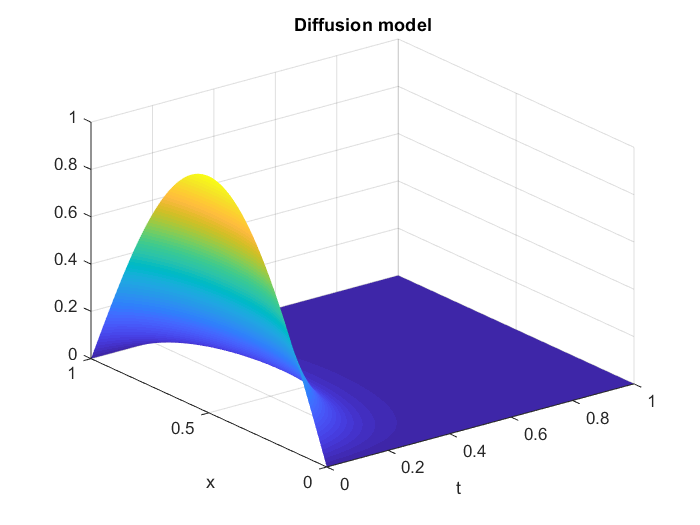

% plot the x-t surface.
figure, surf(t,x,u);
hold on;
shading interp;
title("Diffusion model");
xlabel("t");
ylabel("x");

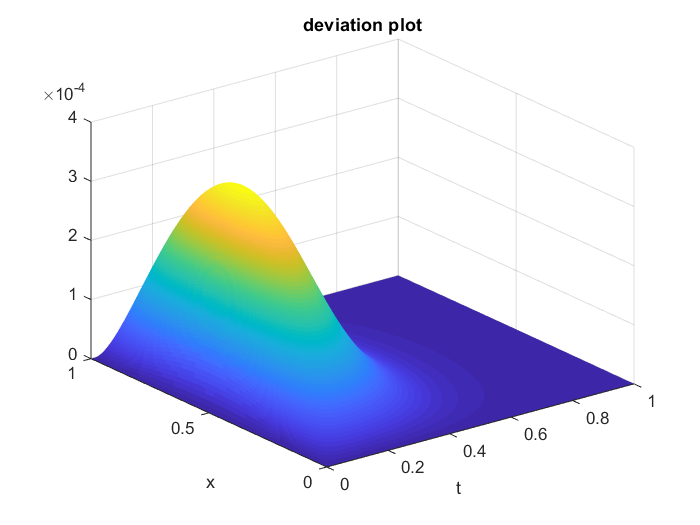

% compare with the precise solution
[T,X]=meshgrid(t,x);
uPrecise=sin(pi*X).*exp(-pi^2*T);
deviation=uPrecise-u;
figure; surf(t,x,deviation,'LineStyle','none');
title("deviation plot");
xlabel("t");
ylabel("x");

We can see that the deviation is controled in a proper range, which is guaranteed by the stable nature of the CN method.